# Task One - Linear Least squares - Two Unkowns

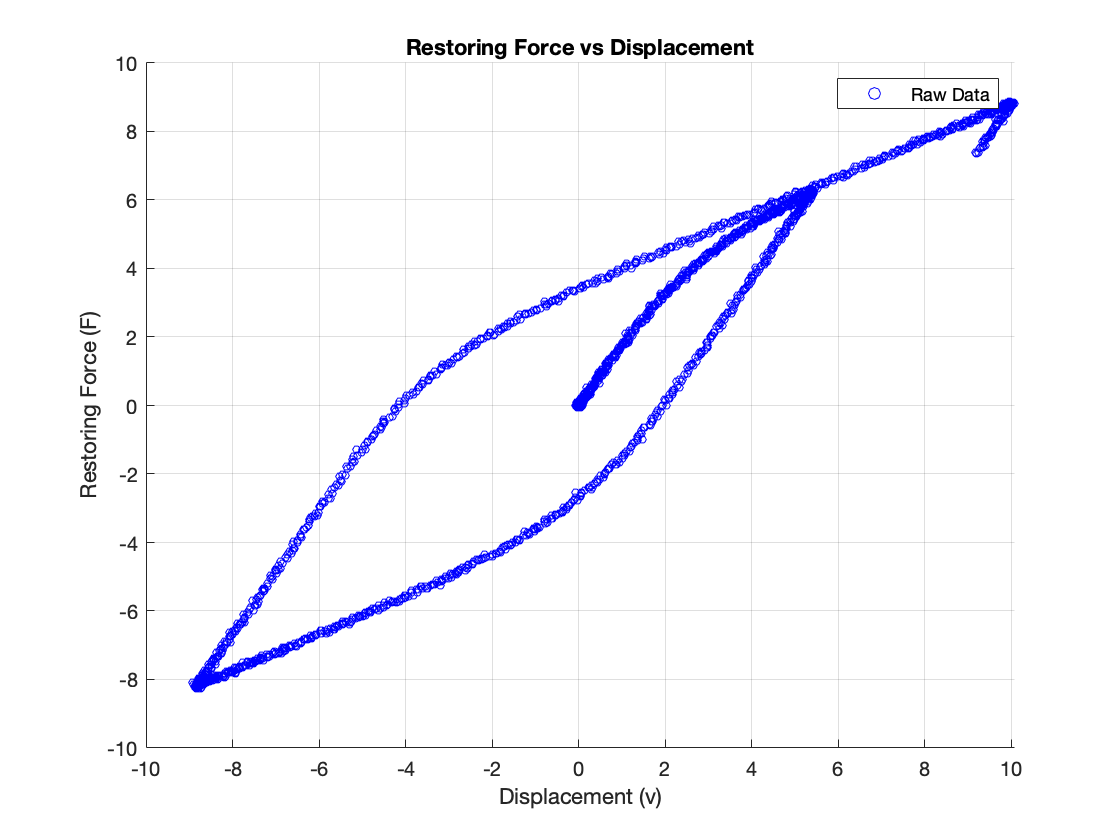

clear
clc

data = load('ParaID_4.mat');
%constants
m = data(1).Mass;
matrix = data(1).Project_Data;
c = data(1).Damping;
%[n,p] = size(matrix);

%variables
dvg = matrix(:,1); 
v = matrix(:,2); 
dv = matrix(:,3); 
ddv = matrix(:,4);
z = matrix(:,5); % Hysteric component

r_force = - m*dvg - m*ddv - c*dv;
A = [v z];
theta = (inv(A.'*A))*(A.'*r_force);
F = A*theta;

% Therefore
alpha = 1 / ((theta(2)/theta(1)) + 1);
k0 = theta(1)/alpha;

scatter(v,r_force,15,'b');
xlabel('Displacement (v)');
ylabel('Restoring Force (F)');
title('Restoring Force vs Displacement');
legend('Raw Data');
grid on;

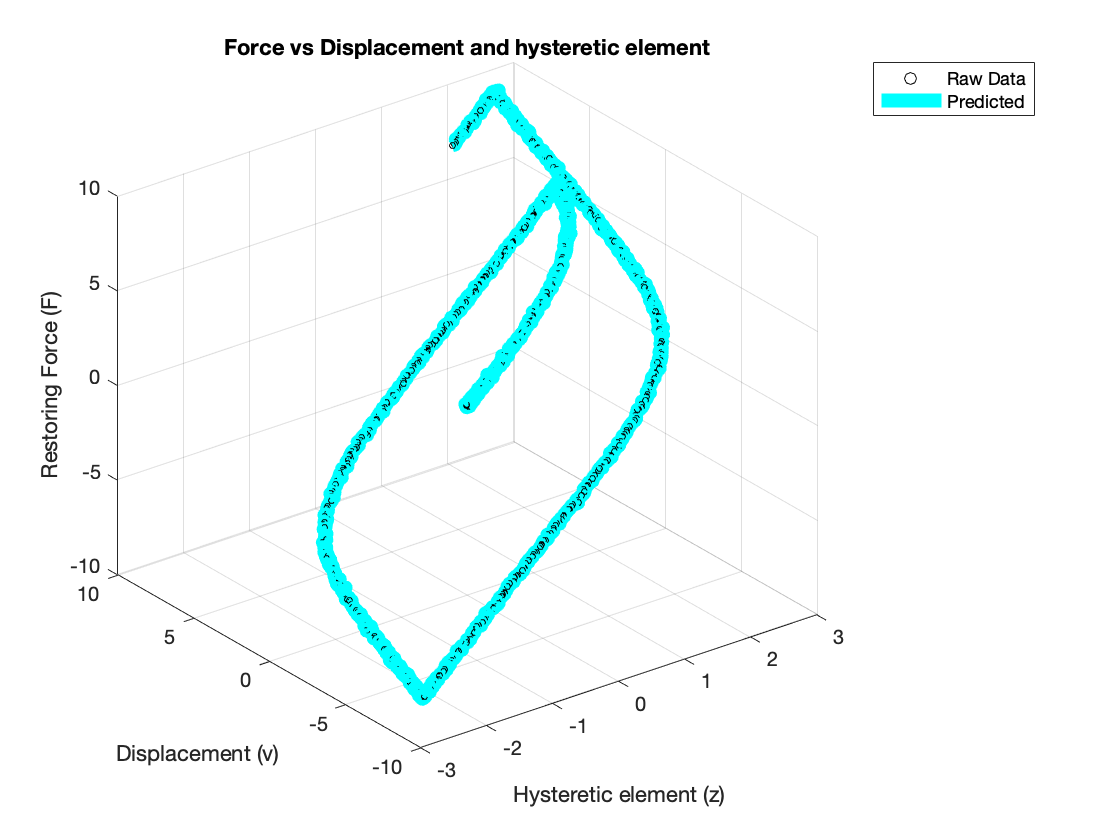

scatter3(z,v,r_force, 10, 'black');
hold on;
plot3(z, v, r_force, 'c', 'LineWidth',7, 'LineJoin',"round");
title('Force vs Displacement and hysteretic element') 
xlabel('Hysteretic element (z)')
ylabel('Displacement (v)')
zlabel('Restoring Force (F)')
legend('Raw Data', 'Predicted');
grid on;
hold off;

## Task One - Cost Function - Two Unkowns

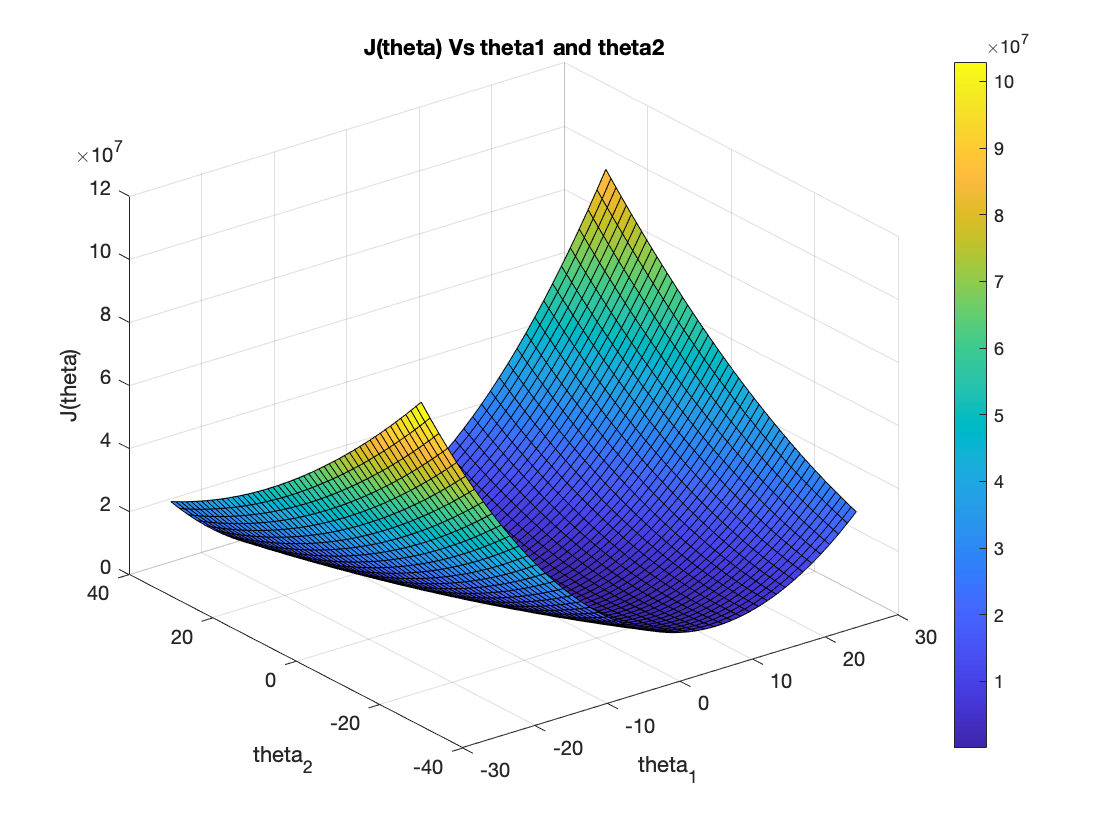

T1 = linspace(-30, 30, 50);
T2 = linspace(-30, 30, 50);
m = length(T1);
p = length(T2);

J = zeros(m,p);
for i = 1 : m
    for k = 1 : p
        J(i,k) = sum((r_force - T1(i).*z - T2(k).*v).^2);
    end
end
[t1, t2] = meshgrid(T1, T2);
J_min = sum(r_force - theta(1).*z - theta(2).*v).^2;

surf(t1, t2, J);
hold on;
plot3(theta(1), theta(2), J_min, 'ro', 'MarkerSize', 2.5, 'LineWidth', 10);
colorbar;
xlabel('theta_1');
ylabel('theta_2');
zlabel('J(theta)');
title('J(theta) Vs theta1 and theta2');
hold Off;

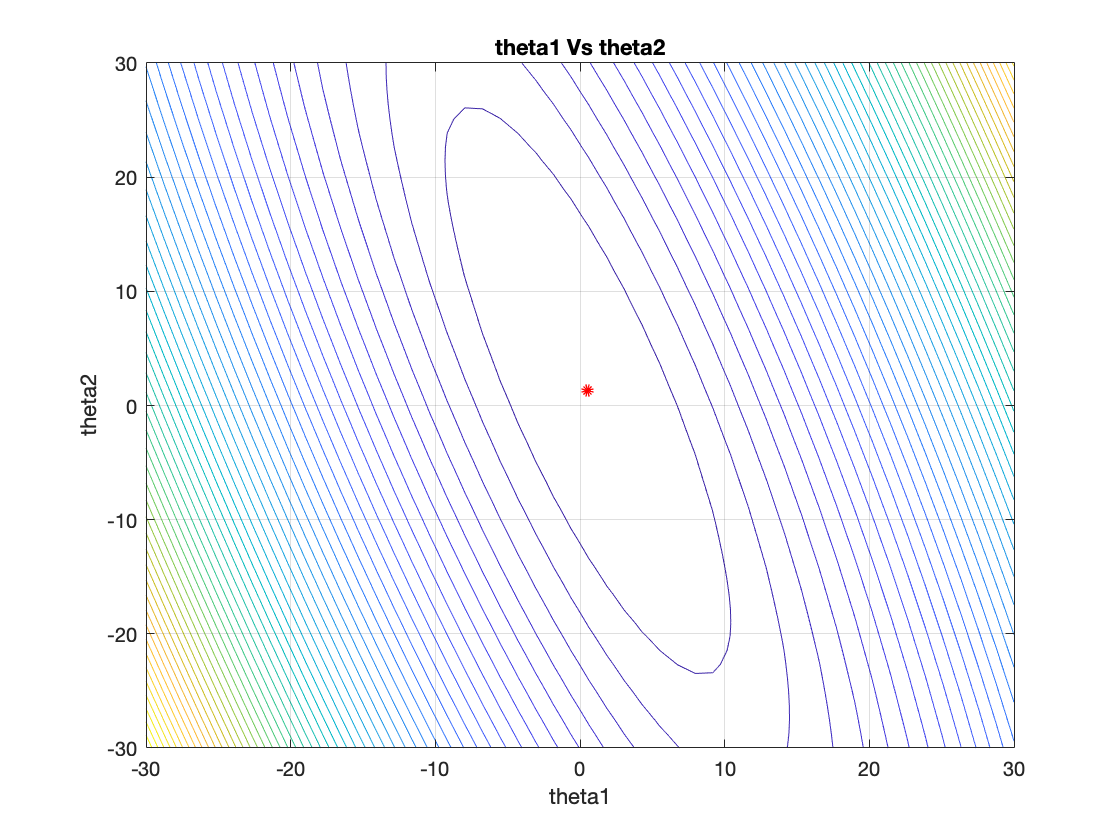


contour(t1, t2, J, 50);
hold on;
plot3(theta(1), theta(2), J_min, 'ro', 'MarkerSize', 2.5, 'LineWidth', 10);
xlabel('theta1');
ylabel('theta2');
title('theta1 Vs theta2');
grid on;
hold off;